# **LAB2 - FILOGENETICA**

**ES1 - Calcolo delle probabilità di un albero filogenetico**

*Compute the probability of the tree depicted in figure as the sum of the probability of individual trees corresponding to possible reconstructions (mutually exclusive events). Assume the following background frequencies and substitution model:*

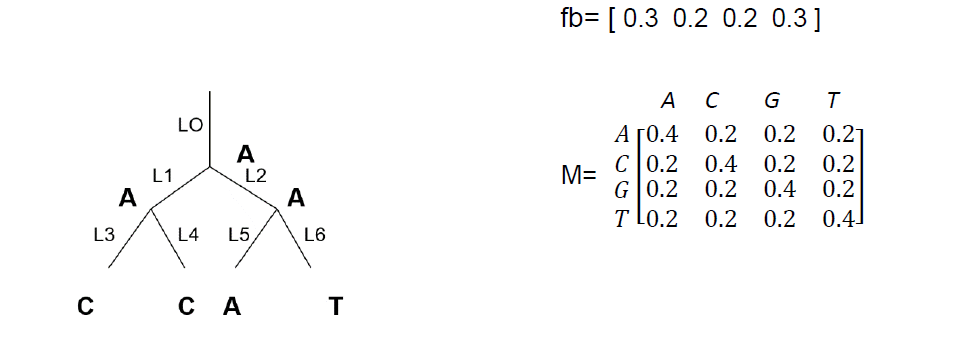

load("ex1.mat");

Sui tre noi disponibili per la variabilità *i, j, k *(**le foglie sono fissate, non variano**) facciamo variare le 4 basi disponibilit (1=A, 2=C, 3=C, 4=G) e calcoliamo la probabilità sulla base della matrice M e delle frequenze di backgroud.

P = 0;
for i=1:4
    for j=1:4
        for k=1:4
            p = fb(i)*M(i,j)*M(j,2)*M(j,2)*M(i,k)*M(k,1)*M(k,4);
            P = P+p;
        end
    end
end

Tutte le combinazioni sono mutuamente esclusive, di conseguenza la probabilità totale è la somma delle probabilità di ogni combinazione.

P

P = 0.0042

Dal momento che le foglie hanno valori fissati, la probabilità è inferiore a 1. Questa, infatti, si ottiene con lo stesso procedimento ma facendo variare tutti i nodi: *i,j,k,l,m,n,o*

P = 0;
for i=1:4
    for j=1:4
        for k=1:4
            for l=1:4
                for m=1:4
                    for n=1:4
                        for o=1:4
                            p = fb(i)*M(i,j)*M(j,l)*M(j,m)*M(i,k)*M(k,n)*M(k,o);
                            P = P+p;
                        end
                    end
                end
            end
        end
    end
end
P

P = 1.0000

**ES2 - Ricostruzione ed esplorazione di un albero filogenetico**

*Given the pre-aligned sequences contained in primates.mat, compute pairwise distances using the 'Jukes-Cantor' formula and the phylogenetic tree with the 'UPGMA' distance method. *

Nella struct `primates `sono indicate 12 specie e le rispettive sequenze (già allineate tra loro) da cui ricostruire l'albero.

load('primates.mat');
primates

primates = 12×1 struct array with fields:
    Header
    Sequence


Le distanze fra le varie sequenze sono storate nella variabile `distances `e calcolate con` seqpdist.`

% Alpha = Alfabeto usato, in questo caso quello nucleotidico
distances = seqpdist(primates,'Method','Jukes-Cantor','Alpha','DNA')

distances =     0.1299    0.1359    0.3313    0.3275    0.3055    0.4813    0.4995    0.4508    0.7052    0.7005    0.7338    0.2165    0.2635    0.2598    0.2449    0.4511    0.4354    0.3776    0.7908    0.7806    0.8502    0.2809    0.2883    0.2994    0.4961    0.5020    0.4983    0.7193    0.7052    0.7437    0.0639    0.1290    0.4781    0.4613    0.3345    0.7987    0.7935    0.8813    0.1123    0.4690    0.4522    0.3074    0.7884    0.7935    0.8871    0.4690    0.4522    0.3074    0.8144    0.7987


L'albero viene costruito con la funzione `seqlinkage, `che interpreta le distanze contenute nel vettore riga derivato da `seqpdist `**automaticamente **(non è necessario interpretare `seqpdist`). E' necessario specificare il metodo utilizzato per la costruzione dell'albero (UPGMA) e, opzionalmente, il "titolo" di ogni frequenza passato attraverso la struct `primates`

UPGMAtree = seqlinkage(distances,'UPGMA',primates)

    Phylogenetic tree object with 12 leaves (11 branches)


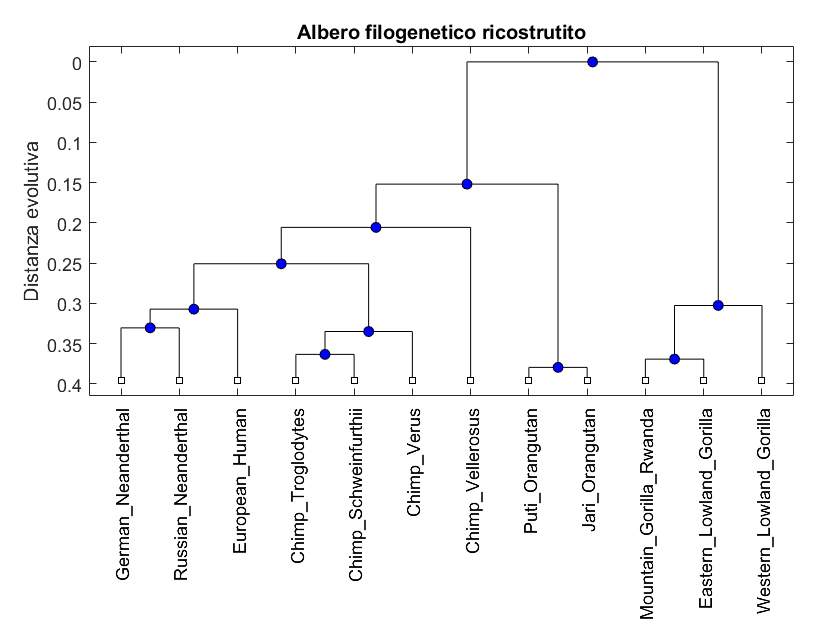

plot(UPGMAtree,'orient','top'); title('Albero filogenetico ricostrutito');
ylabel('Distanza evolutiva')

`UPGMAtree `è un oggetto `phytree `specifico del Bioinformatics Toolbox

*You can explore the phylogenetic tree by considering the nodes (leaves and branches) within a patristic distance of 0.3 from the 'European Human' entry and reduce the tree to the sub-branches of interest by pruning away non-relevant nodes.*

Vengono estratti i nomi delle foglie 

names = get(UPGMAtree,"LeafNames")

names = 12×1 cell array
    {'German_Neanderthal'     }
    {'Russian_Neanderthal'    }
    {'European_Human'         }
    {'Chimp_Troglodytes'      }
    {'Chimp_Schweinfurthii'   }
    {'Chimp_Verus'            }
    {'Chimp_Vellerosus'       }
    {'Puti_Orangutan'         }
    {'Jari_Orangutan'         }
    {'Mountain_Gorilla_Rwanda'}
    {'Eastern_Lowland_Gorilla'}
    {'Western_Lowland_Gorilla'}


Con la funzione `select` vengono individuate le foglie che soddisfano la condizione imposta. La funzione `select `**effettua l'operazione di ricerca tramite query: richiede quindi il database su cui ricercare **(l'albero in questo caso) e i **parametri di ricerca. **

`reference `= la foglia da cui calcolare le distanze, ovvero la 3 *european_human*

`criteria = `Il criterio con cui effettuare la scelta

`threshold = `La soglia su cui basare il criterio, 0.3

[~,h_leaves] = select(UPGMAtree,'reference',3,'criteria','distance','threshold',0.3)

h_leaves = 12×1 logical array
   1
   1
   1
   1
   1
   1
   0
   0
   0
   0


`h_leaves `è un vettore booleano con `true `in corrisponenza dell'indice delle foglie che soddisfano il criterio di ricerca impostato nella query.

subtree_names = names(h_leaves);

Si crea ora un nuovo albero che contenga solamente le foglie che soddisfano il criterio impostato sulla distanza. Per fare ciò, si crea un sottoalbero tramite la funzione `prune, `che elimina le foglie selezionate in input da un albero.

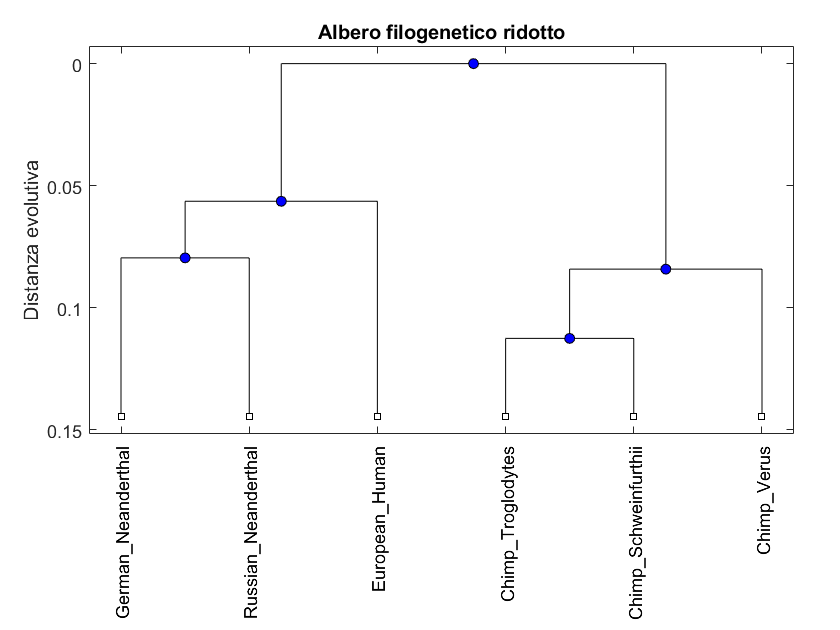

pruned_tree = prune(UPGMAtree,~h_leaves);
plot(pruned_tree,'orient','top'); title('Albero filogenetico ridotto');
ylabel('Distanza evolutiva')

Tutte le foglie in questo albero non sono più distanti tra loro di 0.3 (in termini di distanza evolutiva);

Una visualizzazione alternativa si ottiene attraverso `view`, che evidenzia all'interno dell'albero completo le foglie indicate dal vettore booleano risultato dalla ricerca con `select`

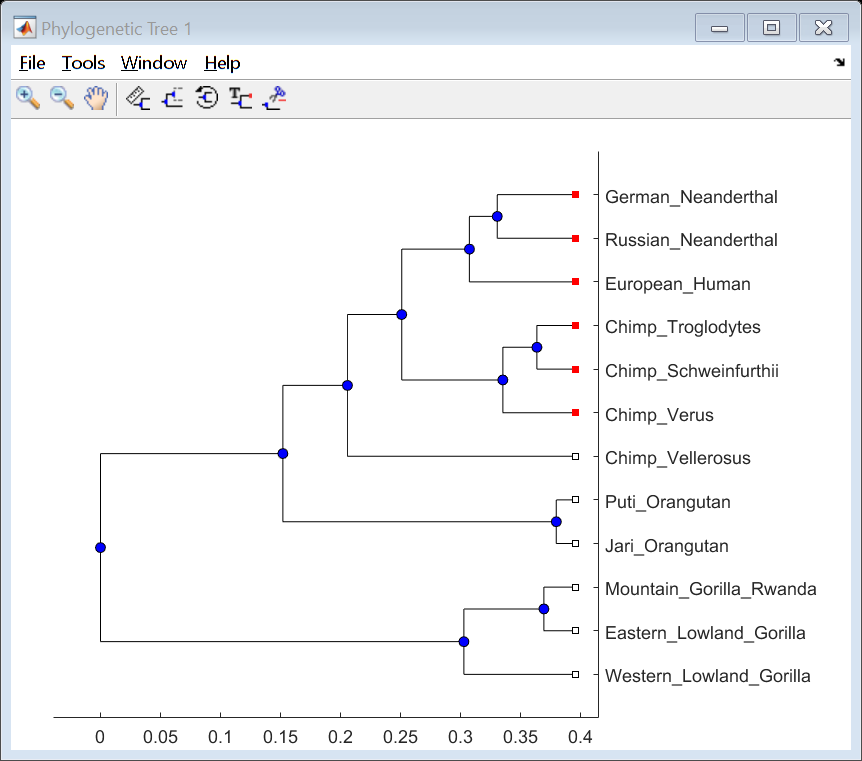

view(UPGMAtree, h_leaves)

**ES3 - Bootstrap**

*The topology of every bootstrap tree is compared with that of the original tree. Any interior branch that gives the same partition of species is counted. Since branches may be ordered differently among different trees but still represent the same partition of species, it is necessary to get the canonical form for each subtree before comparison. In a canonical tree the leaves are ordered alphabetically and the branches are ordered first by their width and then alphabetically by their first element. Apply bootstrap analysis with 100 replicates.*

Il metodo del **bootstrap **viene utilizzato per determinare la validità di un albero costruito. Questo metodo si basa sulla generazione di nuovi alberi **fittizzi** ottenuti dal riarrangiamento delle sequenze che ne costituiscono le foglie, andando a scambiare casualmente varie colonne dell'allineamento (anche con ripetizione). Dai nuovi alberi fittizzi si valuta, poi, se le loro strutture sono presenti anche nell'albero originale

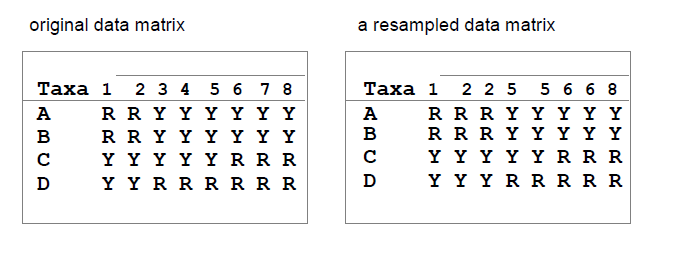

load('primates.mat');

Arbitrariamente, si sceglie di effettuare 100 iterazioni

num_boots = 100;
num_seqs = length(primates); % Numero di specie
seq_len = length(primates(1).Sequence); % Lunghezza di sequenze

I 100 allineamenti casuali vengono salvati in un array di celle `boots,` che memorizzerà ognuno degli allineamenti in una delle celle.

boots = cell(num_boots,1);
for n=1:num_boots

Attraverso la funzione randrample si generano le posizioni relative agli allineamenti casuali. Impostando il parametro replacement a true otteniamo ripetizioni nel riarrangiamento.

    reorder_index = randsample(seq_len,seq_len,true);

Creiamo ora le sequenze fittizie sulla base degli indici di `randsamples`, che allochiamo all'interno dell'array della struct `bootseq `(dello stesso tipo di `primates`) 

    for i=num_seqs:-1:1 % Prosegue al contrario per questioni di allocazione di memoria
        bootseq(i).Header = primates(i).Header; % Il nome della sequenza non deve cambiare
        bootseq(i).Sequence = primates(i).Sequence(reorder_index);
        bootseq(i).Sequence = strrep(bootseq(i).Sequence,' ',''); % Rimuoviamo i GAP
    end
        boots{n} = bootseq;
end

In un nuovo array di celle `boot_trees `della stessa dimensione di `boots `si creano gli alberi costruiti sulla base di nuovi allineamenti riordinati.

boot_trees = cell(num_boots,1);
for n=1:num_boots
    dist = seqpdist(boots{n},'Method','Jukes-Cantor','Alpha','DNA');
    boot_trees{n} = seqlinkage(dist,'UPGMA',boots{n});
end

A questo punto sono disponibili l'albero originale `UPGMAtree `ed i 100 alberi fittizzi costruiti sulla base del ricampionamento casuale `boot_trees. `Il confronto viene effettuato convertendo gli alberi in una **forma canonica matriciale **ottenuta tramite la funzione `getcanonical: `Il confronto avviene tra tutti i sottoalberi possibili di ogni albero di bootstrap con tutti i sottoalberi possibili dell'albero originale. **Il numero di possibili sottoalberi è sempre pari al numero di foglie meno uno. **

Inizialmente, troviamo tutti i sottoalberi (in forma canonica) dell'albero originale, salvati poi in `orig_pointers.`

for i=num_seqs-1:-1:1 % Scorre tutti i num_seqs-1 nodi che possono generare sottoalberi
    branch_pointer = i+num_seqs; % Il pointer deve "saltare" i primi nodi, che sono quelli 
                                 % riferiti alle foglie (non generano sottoalberi)           

Il sottoalbero relativo al nodo indicato da `branch_pointer `è ottenuto con `subtree`, che da un albero e dall'indice di un nodo ricava il sottoalbero ricavato da quel nodo. 

    sub_tree = subtree(UPGMAtree,branch_pointer);
    orig_pointers{i} = getcanonical(sub_tree); % La forma canonica del sottoalbero
    orig_species{i} = sort(get(sub_tree,'LeafNames')); % Salviamo anche i nomi
end

Lo stesso procedimento viene effettuato anche per tutti gli alberi di boostrap, le cui forme canoniche verranno savate questa volta in una matrice di celle `clusters_pointers`

for i=num_boots:-1:1
    for j=num_seqs-1:-1:1 % Scorre tutti i num_seqs-1 nodi che possono generare sottoalberi
        branch_pointer = j+num_seqs; % Il pointer deve "saltare" i primi nodi, che sono quelli
                                     % riferiti alle foglie (non generano sottoalberi)
        sub_tree = subtree(boot_trees{i},branch_pointer);
        cluster_pointers{i,j} = getcanonical(sub_tree); % La forma canonica del sottoalbero
        cluster_species{i,j} = sort(get(sub_tree,'LeafNames')); % Salviamo anche i nomi
    end
end

Si contano ora il numero di sottostrutture nell'albero originale che si ritrovano negli alberi di bootstrap attraverso al funzione `isequal, `scorrendo tutti gli `i` sottoalberi origininali e i `j = num_boots*(num_seqs-1) `(**Vedi indicizzazione di matrice attraverso EQUIVALENT SINGLE INDEX [sub2ind/ind2sub]**)

count = zeros(num_seqs-1,1);
for i=num_seqs-1:-1:1 % Con i accediamo a orig_pointers
    for j=1:num_boots*(num_seqs-1) % Accediamo a cluster_pointers attraverso j utilizzandolo come
                                   % come 'equivalent single index'. 
                                   % In alternativa --> sub2ind / ind2sub
        if isequal(orig_pointers{i},cluster_pointers{j})
            if isequal(orig_species{i},cluster_species{j})
                % Entro in questo if quando ritrovo la stessa struttura e
                % lo stesso nome di specie nel j-esimo albero di bootstrap
                count(i) = count(i)+1;
            end
        end
    end
end

*The confidence information associated with each branch node can be stored within the tree by annotating the node names. Thus, you can create a new tree, equivalent to the original primates tree, and annotate the branch names to include the confidence levels computed above. Select the branch nodes with a confidence level greater 0.9.*

Convertiamo il conteggio in frequenza di occorrenza, dividendo ogni valore in `count `per il numero totale di bootstrap effettuati: ogni valore di `Pc`, quindi, contiene la percentuale di similitudine di ogni nodo gli alberi di bootstrap con l'albero originale.

Pc = count./num_boots;
Pc = Pc'

Pc =     1.0000    1.0000    0.9900    0.9900    0.5600    0.5600    1.0000    0.4400    0.4300    0.4300    0.4300


Viene rappresentato nuovamente l'albero, visualizzando in corrispondenza di ogni nodo anche la confidenza relativa al nodo stesso. Con `get` ricaviamo alcuni parametri utili per la visualizzazione

[ptrs,dist,names] = get(UPGMAtree,'Pointers','Distances','NodeNames');

Accodiamo a `names` il valore di confidenza per ogni nodo e costruiamo un nuovo albero con i nuovi nomi attraverso `phytree`, che richiede i pointers ai nodi e le distanze tra essi (uguali a quelli dell'albero originale e ottenuti con la funzione `get`) e i nomi delle sequenze (opzionale)

for i = 1:num_seqs-1
    branch_pointer = i+num_seqs;
    names{branch_pointer} = [names{branch_pointer} ' Conf=' num2str(Pc(i)*100)];
end
tr = phytree(ptrs,dist,names);

Plottiamo nuovamente l'albero, evidenziando i nodi caratterizzati da un livello di confidenza molto elevato ( >0.9 )

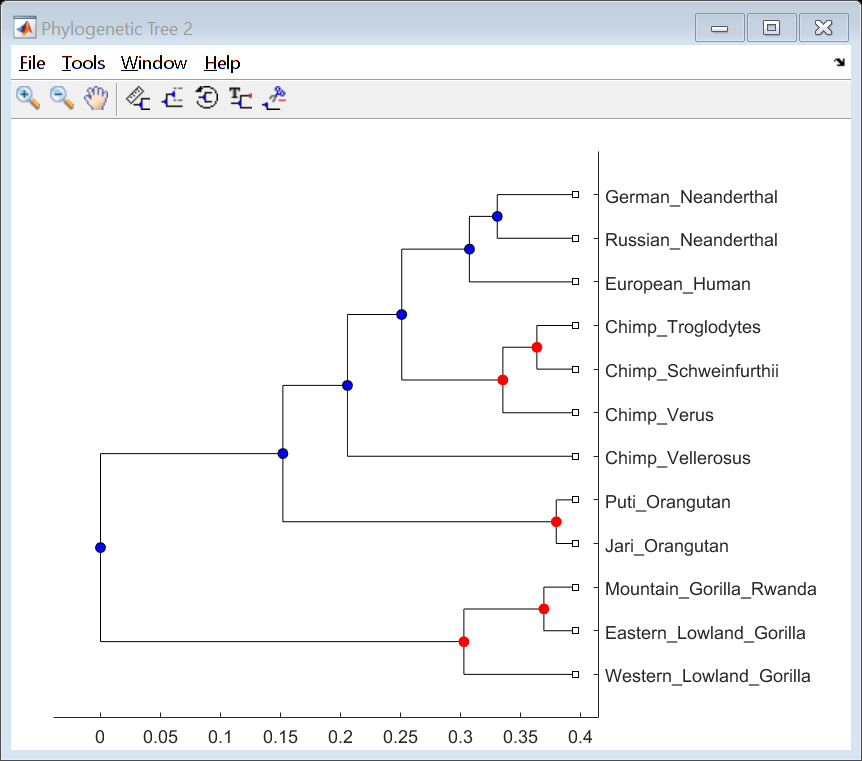

high_conf_b = find(Pc>0.9)+num_seqs;
view(tr,high_conf_b)